故障未知的实验, 电机最小转速是0

clear
clc
 
ulogOBJ = ulogreader("log_10_2022-4-12-15-28-56.ulg");
msg = readTopicMsgs(ulogOBJ);

## 确定known_logger的序号，提取log数据

更换log文件后需要修改下面的数值，找到msg中对应的known_logger的序号是多少。

 
% 获取known_logger数据
known_logger = msg.TopicMessages{12};
% 生成相对时间
log_time = known_logger.timestamp;
time = seconds(log_time);

% 读取数据
tDes = known_logger.tdes;

figure(11)
clf
subplot(2,1,1)
plot(time,tDes(:,1))
hold on
plot(time,tDes(:,2))
hold on
plot(time,tDes(:,3))
hold on
plot(time,tDes(:,4))
legend('rotor 1','rotor 2','rotor 3','rotor 4','Location',"west")

## input_rc

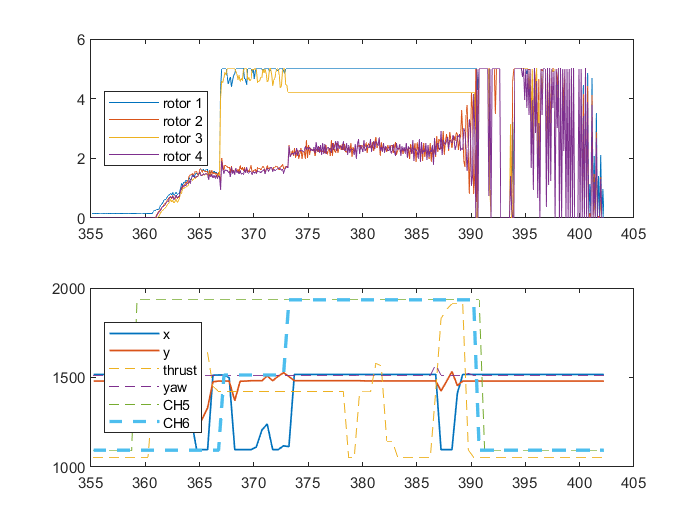

input_rc = msg.TopicMessages{11};
% 生成相对时间
log_time = input_rc.timestamp;
time = seconds(log_time);
[sample_count,~] = size(log_time);
% 获取数据
rc = input_rc.values;


subplot(2,1,2)
plot(time,rc(:,1),'LineWidth',1)
hold on
plot(time,rc(:,2),'LineWidth',1)
hold on
plot(time,rc(:,3),'--')
hold on
plot(time,rc(:,4),'--')
hold on
plot(time,rc(:,5),'--')
hold on
plot(time,rc(:,6),'--','LineWidth',2)
legend('x','y','thrust','yaw','CH5','CH6','Location',"west")